I = imread("ryj_rajsa.ppm");
% imwrite(I,"examples\srodek_ciezkosci\hdmi_vga_zybo\rajs.ppm",'ppm')
%I = imresize(I,[64 64]);
I = imresize(I,[128 128]);
I(1, 1, :) = [69 69 69];

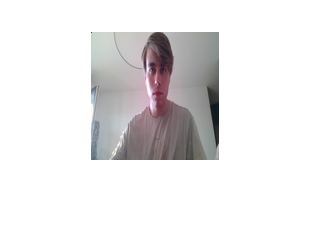

imshow(I)

size(I)

ans =    128   128     3


YCC = zeros([128, 128, 3]);

double_matrix = [0.299 0.587 0.114; -0.168736 -0.331264 0.5; 0.5 -0.418688 -0.081312]

double_matrix =     0.2990    0.5870    0.1140
   -0.1687   -0.3313    0.5000
    0.5000   -0.4187   -0.0813


const = [0; 128; 128]

const =      0
   128
   128


for i = 1:128
    for j = 1:128
        R = I(i, j, 1);
        G = I(i, j, 2);
        B = I(i, j, 3);
        YCC(i,j,:) = double_matrix * double([R;G;B]) + const;
    end
end
YCC = uint8(YCC);

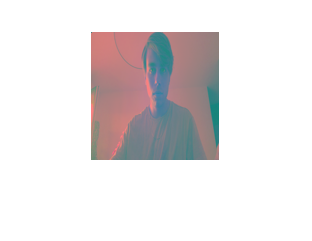

imshow(YCC)

YCC = zeros([128, 128, 3]);

double_matrix = [0.299 0.587 0.114; -0.168736 -0.331264 0.5; 0.5 -0.418688 -0.081312];
m = fi(double_matrix, 1, 18, 17)

m =     0.2990    0.5870    0.1140
   -0.1687   -0.3313    0.5000
    0.5000   -0.4187   -0.0813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

const = [0; 128; 128];
const = fi(const, 0, 8, 0)

const =      0
   128
   128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 8
        FractionLength: 0

n = numerictype(1,9,0);
for i = 1:128
    for j = 1:128
        R = fi(I(i, j, 1), 0, 8, 0);
        G = fi(I(i, j, 2), 0, 8, 0);
        B = fi(I(i, j, 3), 0, 8, 0);
        Y = quantize(m(1, 1) * R, n) + quantize(m(1, 2) * G, n) + quantize(m(1, 3) * B, n);
        Cb = quantize(m(2, 1) * R, n) + quantize(m(2, 2) * G, n) + quantize(m(2, 3) * B, n);
        Cr = quantize(m(3, 1) * R, n) + quantize(m(3, 2) * G, n) + quantize(m(3, 3) * B, n);
        YCC(i,j,:) = [Y; Cb; Cr] + const;
    end
end
YCC = uint8(YCC);

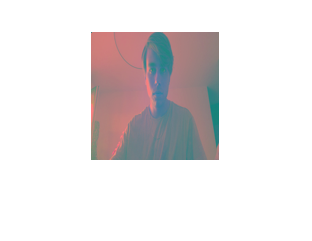

imshow(YCC)

pixel = YCC(1, 1, :)

pixel = 1×1×3 uint8 array
pixel(:,:,1) =

   67


pixel(:,:,2) =

   127


pixel(:,:,3) =

   127


bin(pixel)

Undefined function 'bin' for input arguments of type 'uint8'.

hex(m)

ans = 3×21 char array
    '09917   12c8b   03a5e'
    '3a99b   35665   10000'
    '10000   329a2   3d65e'


hex(const)

ans = 3×2 char array
    '00'
    '80'
    '80'


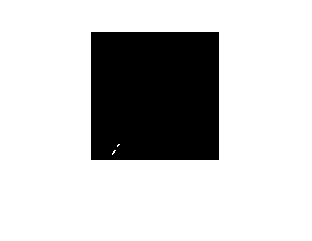

% Ta = 100;
% Tb = 120;
% Tc = 132;
% Td = 170;
% Ta = 90;
% Tb = 119;
% Tc = 117;
% Td = 163;
Ta = 80;
Tb = 120;
Tc = 100;
Td = 170;
binary = zeros(128, 128, 3);
for row = 1:128
    for col = 1:128
        Cb = YCC(row, col, 2);
        Cr = YCC(row, col, 3);
        if (Cb > Ta && Cb < Tb && Cr > Tc && Cr < Td)
            binary(row, col, :) = 255;
        else
            binary(row, col, :) = 0;
        end
    end
end

imshow(uint8(binary))

m00 = 0;
m10 = 0;
m01 = 0;
for row = 1:128
    for col = 1:128
        m00 = m00 + (binary(row, col, 1)/255);
        m10 = m10 + ((row - 1)*(binary(row, col, 1)/255));
        m01 = m01 + ((col - 1)*(binary(row, col, 1)/255));
    end
end
m00
x_sc = round(m10/m00)
m10
y_sc = round(m01/m00)
m01

for row = 1:128
    for col = 1:128
        if col == y_sc + 1 || row == x_sc + 1
            binary(row, col, 1) = 255;
            binary(row, col, 2) = 0;
            binary(row, col, 3) = 0;
        end
    end
end
imshow(uint8(binary))